addpath(genpath('Test Signals'));

[diracStereo, fs] = audioread('diracTest.wav');
[dirac] = [diracStereo, diracStereo];
[essStereo, fs] = audioread('sineSweep.wav');
[ess] = [essStereo, essStereo];
[pinkNoiseStereo, fs] = audioread('pinkNoise.wav');
[pinkNoise] = [pinkNoiseStereo, pinkNoiseStereo];
[guitar, fs] = audioread('Guitar.wav');

% Initialize plugin
reverb = Reverb(); 

buff_length = 480;
% Set parameters
reverb.feedback = 0.9;
reverb.damping = 0.4;
reverb.mix = 100;
reverb.stereoSeperation = 100;
reverb.masterGain = 15;

## Dirac

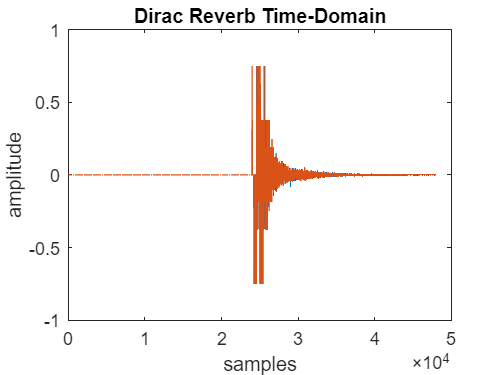

dirac_out = reverb.process(dirac);

figure(1);
plot(dirac_out);
title('Dirac Reverb Time-Domain');
xlabel('samples');
ylabel('amplitude');

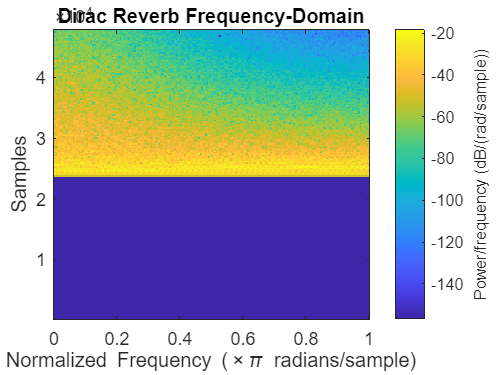


win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(dirac_out(:,1), hamming(win_length), overlap_length, nfft);
title('Dirac Reverb Frequency-Domain');

## ESS

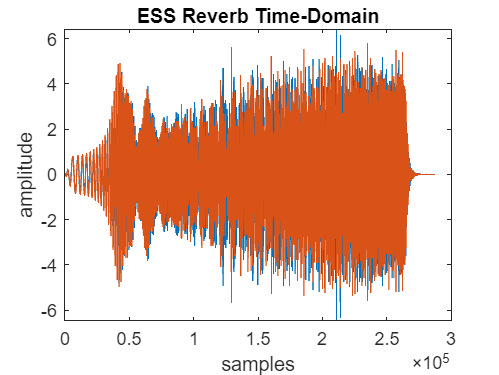


ess_out = reverb.process(ess);

figure(3);
plot(ess_out);
title('ESS Reverb Time-Domain');
xlabel('samples');
ylabel('amplitude');

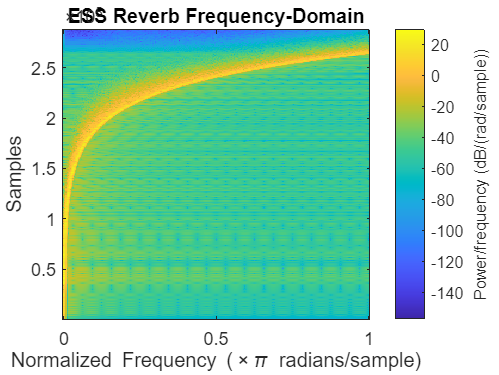



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(4);
spectrogram(ess_out(:,1), hamming(win_length), overlap_length, nfft);
title('ESS Reverb Frequency-Domain');

## Pink Noise

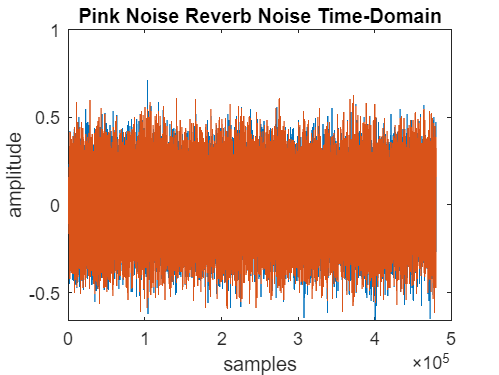


pinkNoise_out = reverb.process(pinkNoise);

figure(5);
plot(pinkNoise_out);
title('Pink Noise Reverb Noise Time-Domain');
xlabel('samples');
ylabel('amplitude');

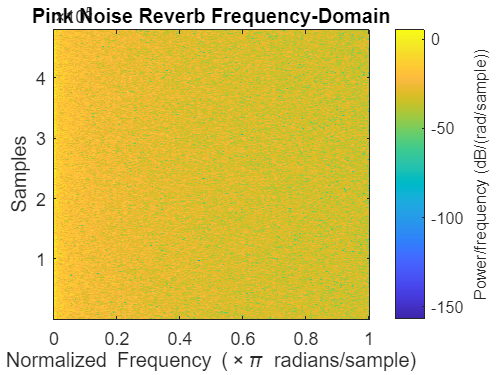



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(pinkNoise_out(:,1), hamming(win_length), overlap_length, nfft);
title('Pink Noise Reverb Frequency-Domain');

## Guitar

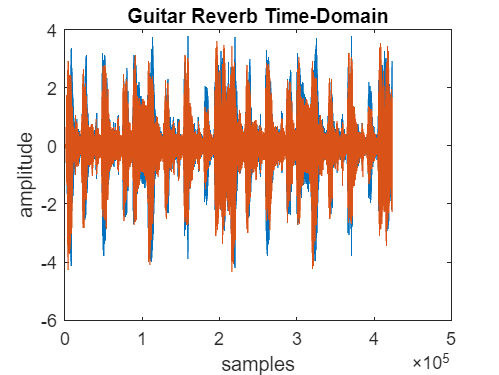


guitar_out = reverb.process(guitar);

figure(7);
plot(guitar_out);
title('Guitar Reverb Time-Domain');
xlabel('samples');
ylabel('amplitude');

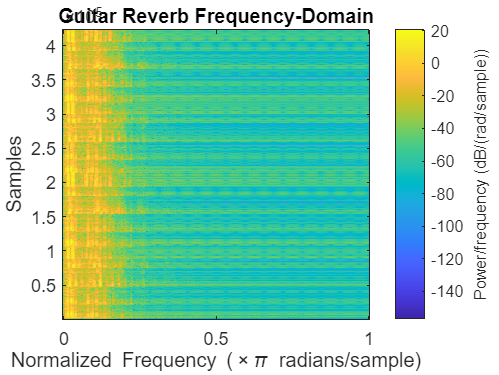



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(8);
spectrogram(guitar_out(:,1), hamming(win_length), overlap_length, nfft);
title('Guitar Reverb Frequency-Domain');

## Reverb

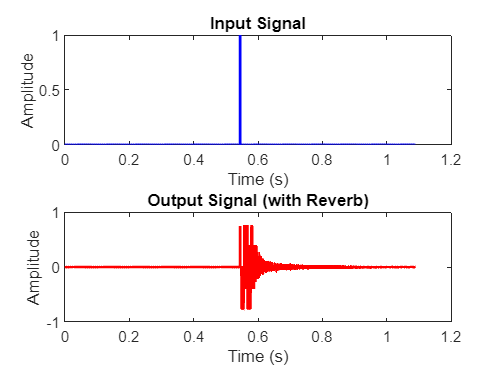

% Plot the input and output signals for comparison
time = (0:length(dirac) - 1) / fs;
figure(9);

subplot(2, 1, 1);
plot(time, dirac, 'b', 'LineWidth', 1.5);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time, dirac_out, 'r', 'LineWidth', 1.5);
title('Output Signal (with Reverb)');
xlabel('Time (s)');
ylabel('Amplitude')

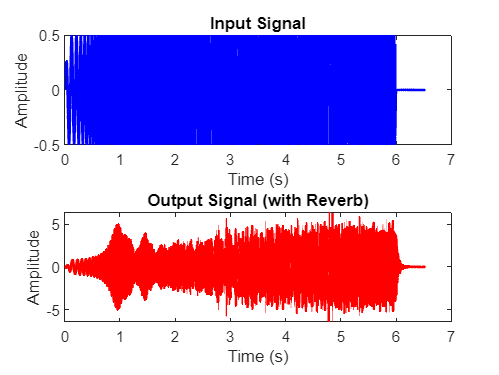


% Plot the input and output signals for comparison
time = (0:length(ess) - 1) / fs;
figure(10);

subplot(2, 1, 1);
plot(time, ess, 'b', 'LineWidth', 1.5);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time, ess_out, 'r', 'LineWidth', 1.5);
title('Output Signal (with Reverb)');
xlabel('Time (s)');
ylabel('Amplitude')

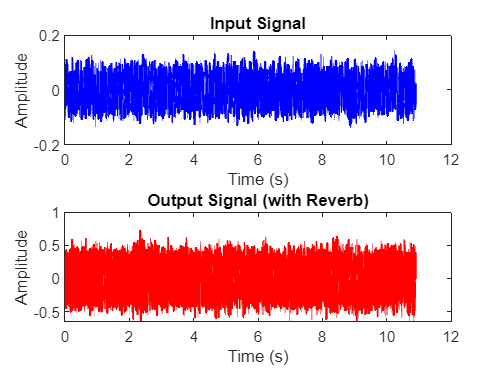


% Plot the input and output signals for comparison

time = (0:length(pinkNoise) - 1) / fs;
figure(11);

subplot(2, 1, 1);
plot(time, pinkNoise, 'b', 'LineWidth', 1.5);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time, pinkNoise_out, 'r', 'LineWidth', 1.5);
title('Output Signal (with Reverb)');
xlabel('Time (s)');
ylabel('Amplitude');

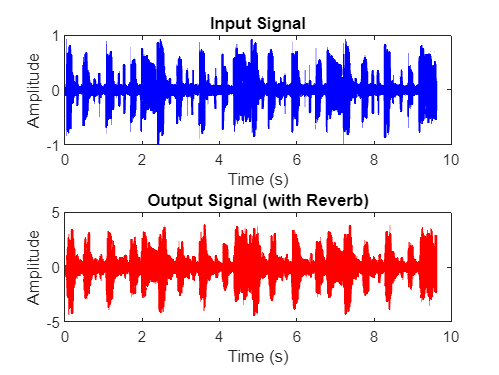


% Plot the input and output signals for comparison

time = (0:length(guitar) - 1) / fs;
figure(12);

subplot(2, 1, 1);
plot(time, guitar, 'b', 'LineWidth', 1.5);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time, guitar_out, 'r', 'LineWidth', 1.5);
title('Output Signal (with Reverb)');
xlabel('Time (s)');
ylabel('Amplitude');

## Low Pass Filter

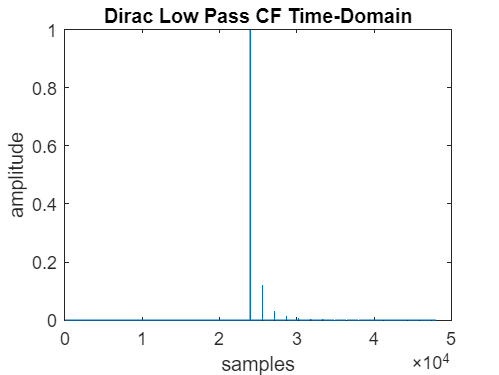

lowPassCF = lowPassCombFilter(1557, 0.8, 0.6); 

buff_length = 480;

% Set parameters

lowPassCF_Dirac_out = lowPassCF.process(dirac);
lowPassCF_ESS_out = lowPassCF.process(ess);
lowPassCF_pinkNoise_out = lowPassCF.process(pinkNoise);

figure(13);
plot(lowPassCF_Dirac_out);
title('Dirac Low Pass CF Time-Domain');
xlabel('samples');
ylabel('amplitude');

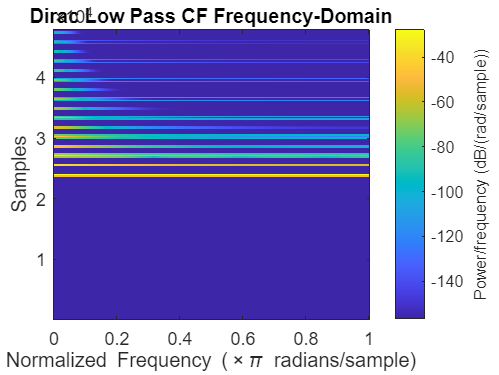


win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(14);
spectrogram(lowPassCF_Dirac_out(:,1), hamming(win_length), overlap_length, nfft);
title('Dirac Low Pass CF Frequency-Domain');

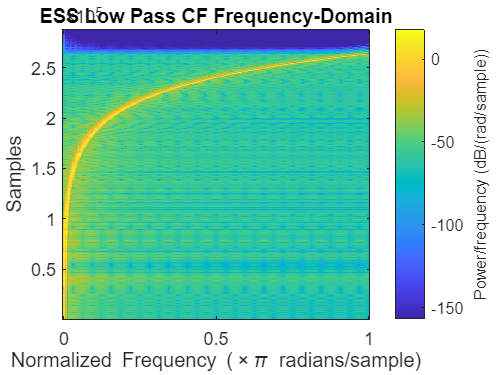


%% 

figure(15);
spectrogram(lowPassCF_ESS_out(:,1), hamming(win_length), overlap_length, nfft);
title('ESS Low Pass CF Frequency-Domain');

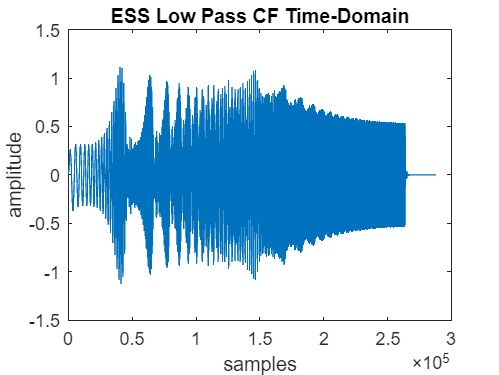


figure(16);
plot(lowPassCF_ESS_out);
title('ESS Low Pass CF Time-Domain');
xlabel('samples');
ylabel('amplitude');

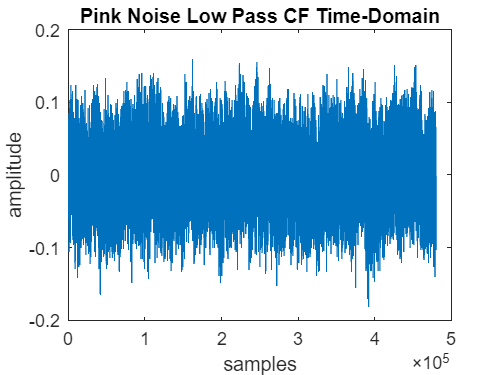


%%

figure(17);
plot(lowPassCF_pinkNoise_out);
title('Pink Noise Low Pass CF Time-Domain');
xlabel('samples');
ylabel('amplitude');

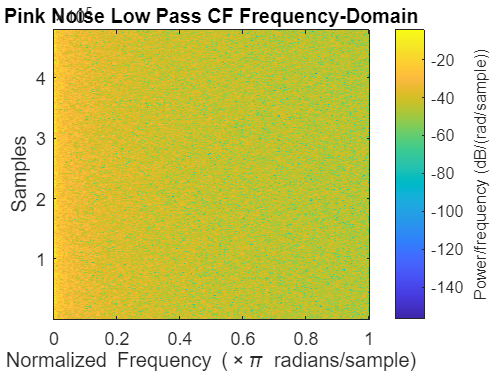


win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(18);
spectrogram(lowPassCF_pinkNoise_out(:,1), hamming(win_length), overlap_length, nfft);
title('Pink Noise Low Pass CF Frequency-Domain');

## All Pass Filter

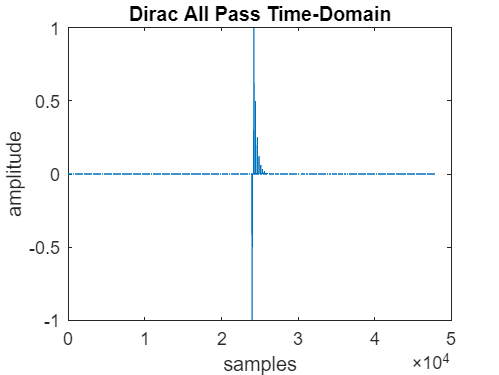

allPass = allPassFilter(225, 0.5); 

buff_length = 480;

% Set parameters

allPass_Dirac_out = allPass.process(dirac);
allPass_ESS_out = allPass.process(ess);
allPass_pinkNoise_out = allPass.process(pinkNoise);


figure(19);
plot(allPass_Dirac_out);
title('Dirac All Pass Time-Domain');
xlabel('samples');
ylabel('amplitude');

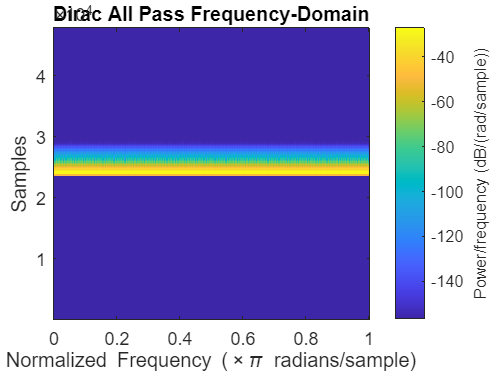


win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(20);
spectrogram(allPass_Dirac_out(:,1), hamming(win_length), overlap_length, nfft);
title('Dirac All Pass Frequency-Domain');

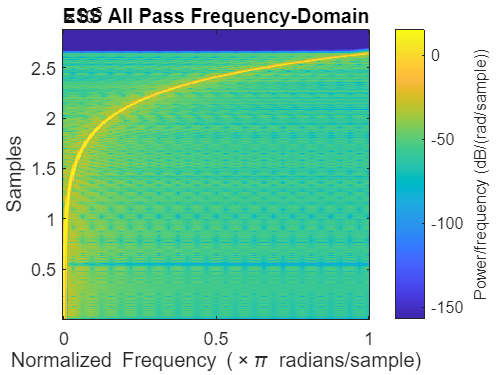


%% 

figure(21);
spectrogram(allPass_ESS_out(:,1), hamming(win_length), overlap_length, nfft);
title('ESS All Pass Frequency-Domain');

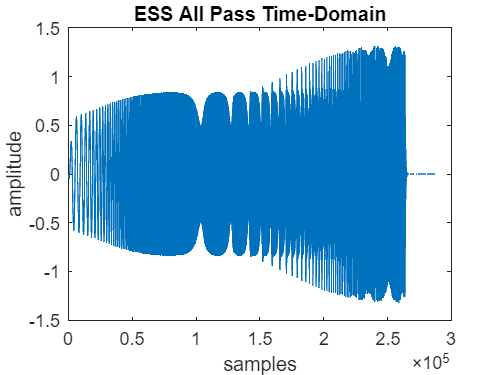


figure(22);
plot(allPass_ESS_out);
title('ESS All Pass Time-Domain');
xlabel('samples');
ylabel('amplitude');

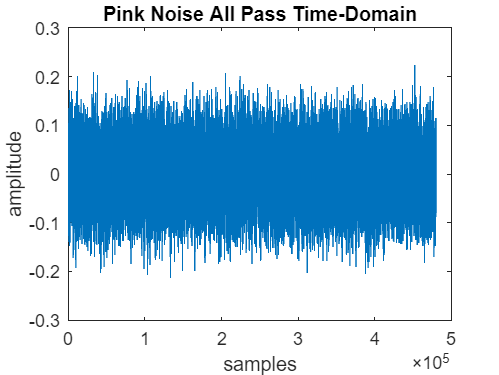


%%

figure(23);
plot(allPass_pinkNoise_out);
title('Pink Noise All Pass Time-Domain');
xlabel('samples');
ylabel('amplitude');

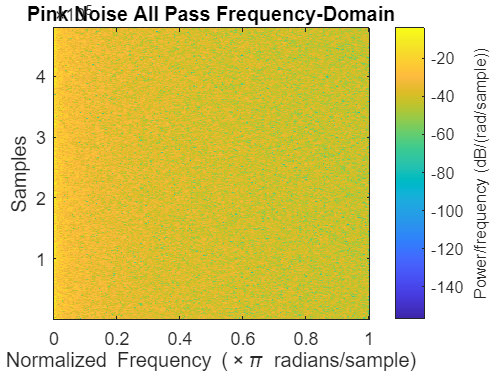


win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(24);
spectrogram(allPass_pinkNoise_out(:,1), hamming(win_length), overlap_length, nfft);
title('Pink Noise All Pass Frequency-Domain');